## **Read , plot and set tdms metaproperties**

tdmsFileName="20241029-120917 FD Curve np1.tdms";% Input the filename for reading and plotting.

tdms_time = tdmsread( tdmsFileName,ChannelGroupName="ChannelGroup1",ChannelName="timestamp");
tdms_force=tdmsread( tdmsFileName,ChannelGroupName="ChannelGroup1",ChannelName="force2x");
tdms_distance=tdmsread( tdmsFileName,ChannelGroupName="ChannelGroup1",ChannelName="distance");

T=tdms_time{1}{:,"timestamp"}

T =          0
    0.1191
    0.2382
    0.3572
    0.4763
    0.5954
    0.7145
    0.8335
    0.9526
    1.0717


F=tdms_force{1}{:,"force2x"}

F =     0.1267
    0.0696
   -0.1064
    0.0024
   -0.0353
    0.0229
   -0.1478
   -0.5605
   -0.4996
   -0.4185


D=tdms_distance{1}{:,"distance"}

D =     2.4426
    2.4749
    2.5550
    2.6667
    2.7732
    2.9319
    3.1406
    3.3239
    3.5362
    3.7617


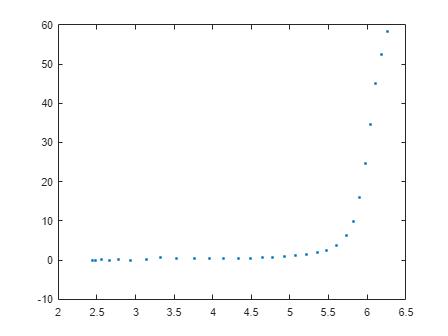

plot(D,-F,'MarkerFaceColor',[0 0.447058823529412 0.741176470588235],...
    'MarkerSize',2,...
    'Marker','o',...
    'LineStyle','none');


% Set Metaproperties

%% Specify the folder containing your .tdms files

folder = "I:\optical tweezer\dna pulling\new project\raw_lambda_before_jump\set4"; % Replace with your actual folder path


% Find all .tdms files in the folder
fileInfo = dir(fullfile(folder, '*.tdms'));
% Loop through each .TDMS file
for n = 1:length(fileInfo)
    fileName = fileInfo(n).name;
    fullFileName = fullfile(folder, fileName);
        % Write metadata to tdms files --
        tdmswriteprop(fileName,"title"," lambda_dna Data")
        tdmswriteprop(fileName,"description","Set_4",...
        ChannelGroupName="ChannelGroup1")
        tdmswriteprop(fileName,["description", "unit_string"],["time","ns"],ChannelGroupName="ChannelGroup1",ChannelName="timestamp")
        tdmswriteprop(fileName,["description", "unit_string"],["end_to_end_distance","um"],ChannelGroupName="ChannelGroup1",ChannelName="distance")
        tdmswriteprop(fileName,["description", "unit_string"],["force","pN"],ChannelGroupName="ChannelGroup1",ChannelName="force2x")
    
end
info=tdmsinfo("20241105-133004 FD Curve 6.tdms") % Check channel list

Error using tdmsinfo
Invalid argument at position 1. The following files do not exist: '20241105-133004 FD Curve 6.tdms'.

info.ChannelList


## **Analysis_FDpattern**


% Picking force peaks

% Find local maxima
maxIndices = islocalmax(-F,"MinProminence",0.5,"MaxNumExtrema",10);

% Display results
clf
plot(-F,"Color",[77 190 238]/255)
hold on

% Plot local maxima
plot(find(maxIndices),-F(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255)
title("Number of extrema: " + nnz(maxIndices))
hold off

force1x_max=-F(maxIndices)
index_max=0
for i=1:length(force1x_max)
    if force1x_max(i)>segmentMean(index+1)
        index_max=index_max+1
    end

end
index_max
length(force1x_max)-index_max
max(force1x_max(1:end-index_max)) % Maximum_force


% Picking minima


% Find local minima
minIndices = islocalmin(-1*force1x,"MinProminence",0.5,"ProminenceWindow",131,...
    "MaxNumExtrema",10);

% Display results
clf
plot(force1x,"Color",[77 190 238]/255)
hold on

% Plot local minima
plot(find(minIndices),force1x(minIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255)
title("Number of extrema: " + nnz(minIndices))
hold off

index_min=0
distance_min=distance(minIndices);
force1x_min=force1x(minIndices);

